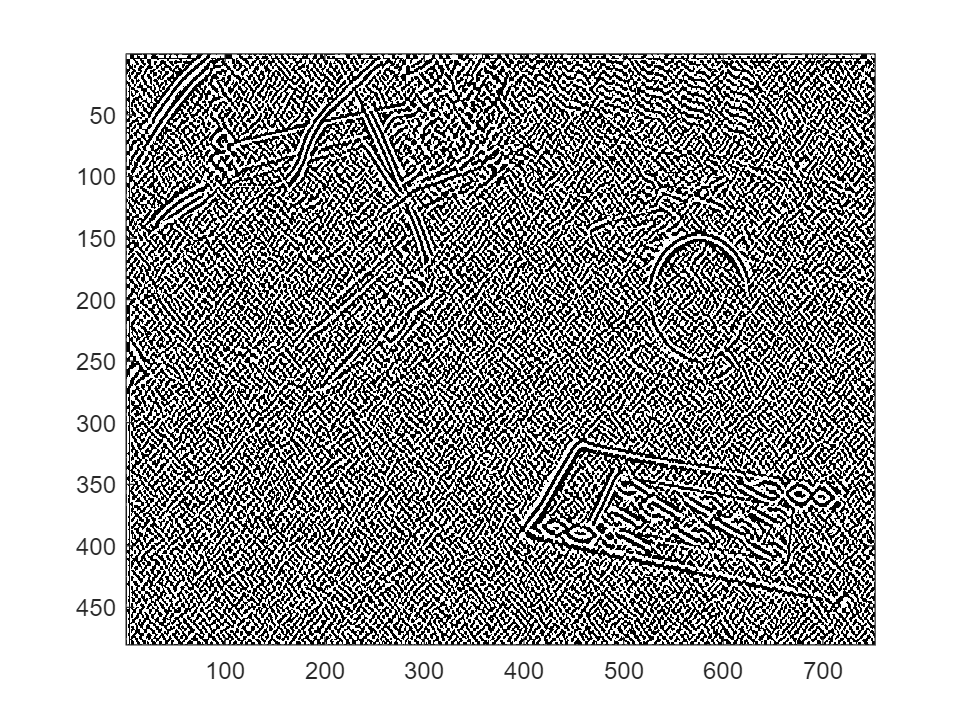

Frame_1 = imread("left5.jpg");
Frame_2 = imread("left6.jpg");
formated_frame_1 = rgb2gray(Frame_1);
formated_frame_2 = rgb2gray(Frame_2);
colormap gray
imagesc(formated_frame_1)

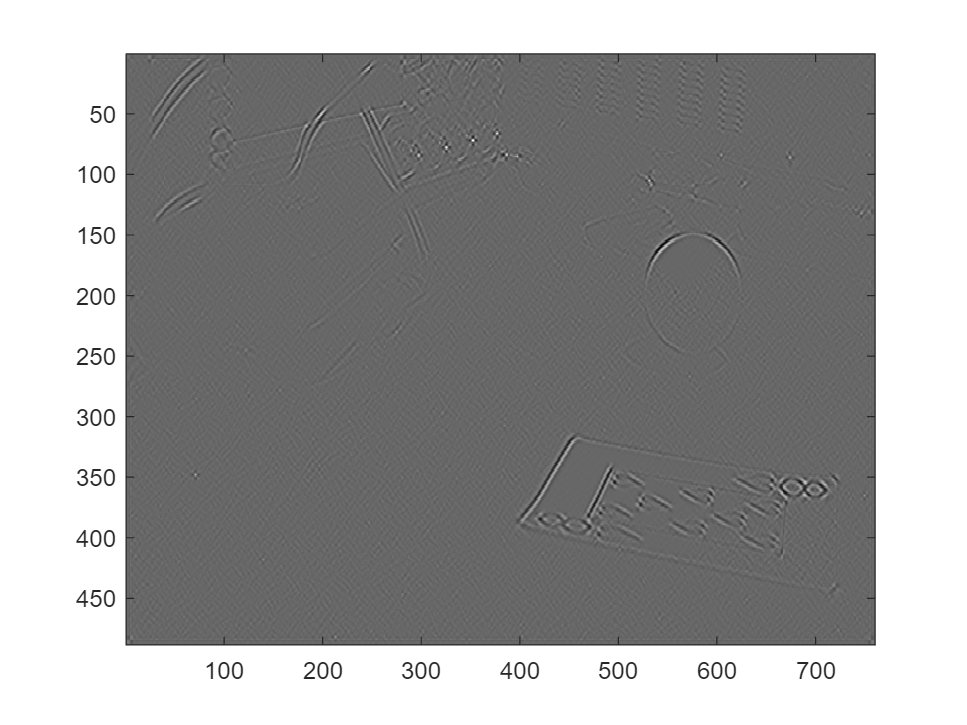

imagesc(formated_frame_2)


rows = 480

rows = 480

cols = 752

cols = 752


w = 100

w = 100

h = 100

h = 100


binary = zeros(rows,cols);
binary2 = zeros(rows,cols);
bwImg = rgb2gray(Frame_1)

bwImg = 480×752 uint8 matrix
    18    29    25    21    26    28    22    31    22    29    27    28    27    30    30    36    29    28    25    23    26    72    74   100    93    96    88    85    73    87    90    91    87   102   111   108    93    93    93   108   110   109    89    98    96   105   108   106    96    85
    26    34    34    33    31    32    30    39    38    33    30    34    31    31    32    37    33    32    25    24    32    77    94   116   105   109   118   115   114   111   112   106   111   110   109   109   113   116   109   111   111   114   109   119   114   110   109   110   114   117
    25    29    32    35    30    29    29    33    33    31    32    33    26    30    34    34    30    31    22    24    34    74   102   114   103   106   112   115   112   111   111   110   107   109   111   110   113   112   111   117   112   112   113   115   111   107   109   115   109   112
    25    29    30    34    32    31    28    28    29    31    34  

Kirsch_kernel_N = [+5 +5 +5;
                   -3  0 -3;
                   -3 -3 -3]

Kirsch_kernel_N =      5     5     5
    -3     0    -3
    -3    -3    -3


convolvedImg_N = conv2(bwImg,Kirsch_kernel_N);
Kirsch_kernel_S = [-3 -3 -3;
                   -3  0 -3;
                   +5 +5 +5]

Kirsch_kernel_S =     -3    -3    -3
    -3     0    -3
     5     5     5


convolvedImg_S = conv2(convolvedImg_N,Kirsch_kernel_S);
Kirsch_kernel_W = [+5 -3 -3;
                   +5  0 -3;
                   +5 -3 -3]

Kirsch_kernel_W =      5    -3    -3
     5     0    -3
     5    -3    -3


convolvedImg_W = conv2(convolvedImg_S,Kirsch_kernel_W);
Kirsch_kernel_E = [-3 -3 +5;
                   -3  0 +5;
                   -3 -3 +5]

Kirsch_kernel_E =     -3    -3     5
    -3     0     5
    -3    -3     5


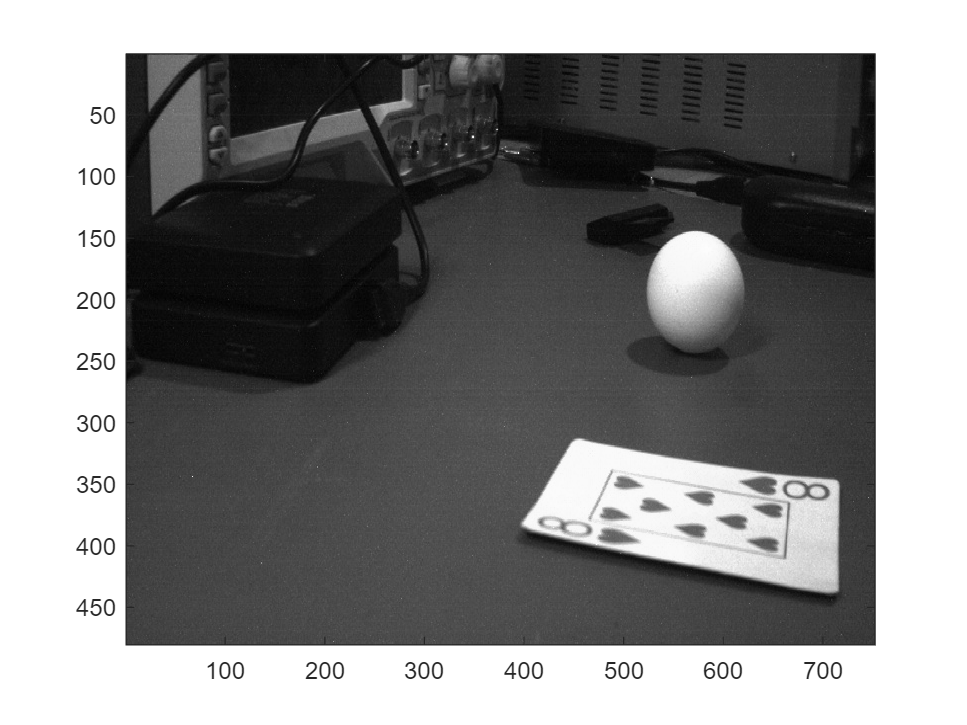

convolvedImg_E = conv2(convolvedImg_W,Kirsch_kernel_E);

imagesc(convolvedImg_E)

for x = 1:cols
    for y = 1:rows
        if (Frame_1(y,x) > 150)
            binary(y,x) = 1;
        end
    end
end

for x = 1:cols
    for y = 1:rows
        if (convolvedImg_E(y,x) > 150)
           binary2(y,x) = 1;
        end
    end
end

%for x = 1:cols:3
%    for y = 1:rows:3
%        image
%    end
%end
binary2

binary2 =      1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     1     1     1     1     0     0     0     0     0     0     1     1     0     0     0     0     0     0     0     0     1     1     0     0     0     1     1     0     0
     1     1     1     1     0     0     0     0     1     1     1     0     1     1     1     1     1     1     0     0     0     1     1     1     1     1     0     0     0     0     1     1     1     1     1     1     1     1     0     0     1     1     1     1     0     1     1     1     1     1
     1     1     1     1     0     0     0     0     1     1     1     0     0     0     1     1     1     1     0     0     0     1     1     1     1     0     0     0     0     0     0     0     1     1     1     1     1     1     0     0     1     1     1     0     0     1     1     1     1     1
     1     1     1     1     0     0     0     0     0     0     0     0     0     0   

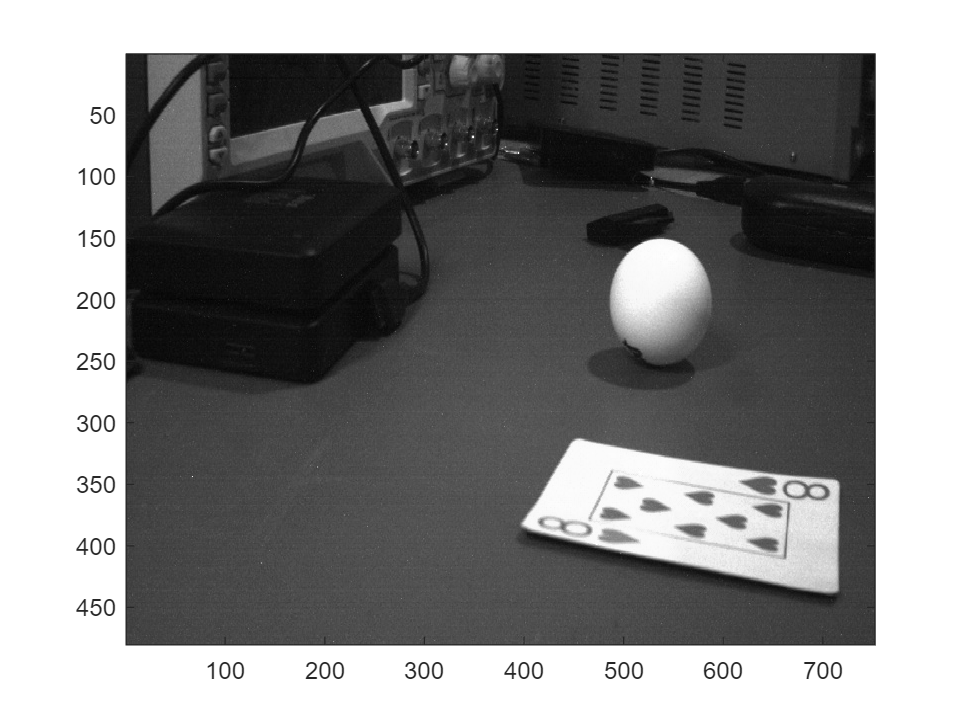

imagesc(binary)

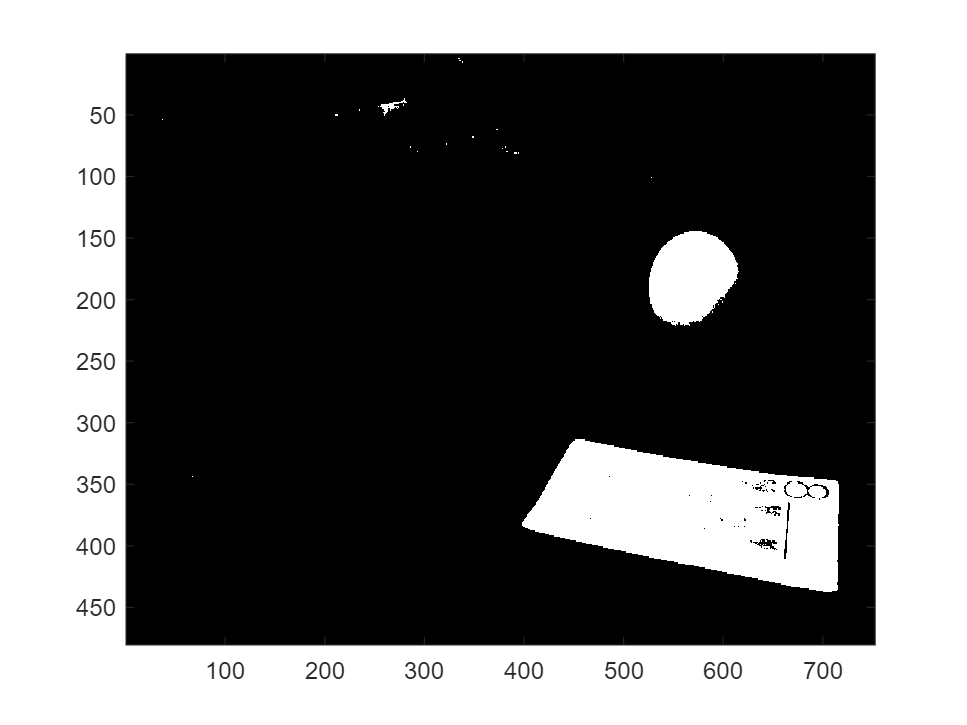

imagesc(binary2)

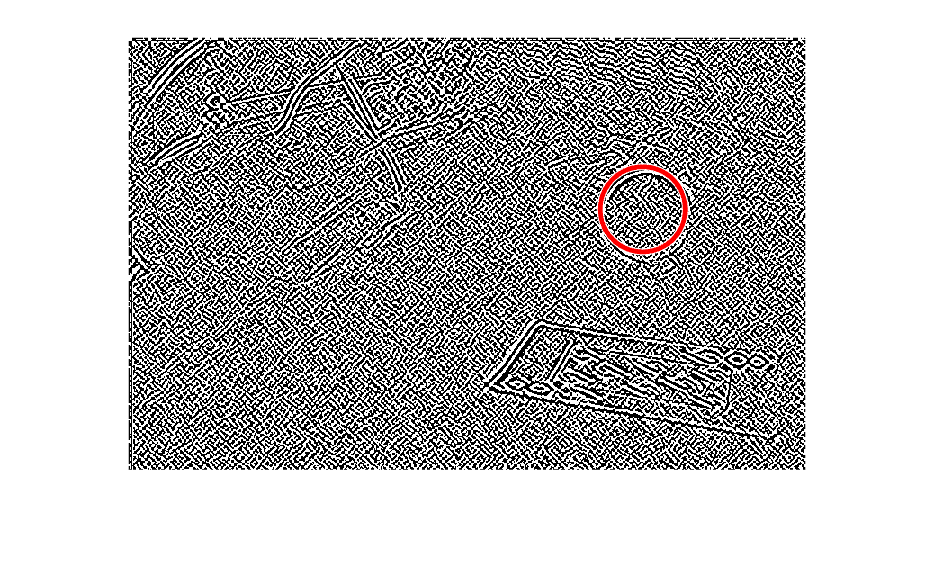

%subplot(1,1,1)
imshow(binary2)

[center, radius] = imfindcircles(Frame_1,[25 75])
viscircles(center, radius, 'Color', 'red')
